音声の読み込み

[audio_in, Fs] = audioread("pon.wav");
n_audio = length(audio_in);     %音声ファイルの長さ
sound(audio_in,Fs)

設定

n_fft = 4096;                   %fft幅
n_shift = 4;                  %シフト幅
frame_size = 1024;              %フレームサイズ

メインループ

audio_out = [];

n = n_fft - n_shift;

関数または変数 'n_fft' が認識されません。


%バッファ
x_buff = zeros(n_fft,2);
y_buff = zeros(n_fft,2);
spectrum_buff= zeros(n_fft/2,2);

tic;

for t = 1:frame_size:(n_audio-frame_size)
    
    x_frame = audio_in(t:t+frame_size,:);
    y_frame = zeros(frame_size,2);
    
    %メインの処理
    for i = 1:frame_size
        %バッファに音を入れる
        x_buff(n,:) = x_frame(i,:);
        
        %バッファから音を出す
        y_frame(i,:) = y_buff(max(1,n-n_fft/2),:);
        
        %ステップを進める
        n = n + 1;
        
        %バッファに音が溜まったら
        if n == n_fft
        
            %FFT
            x_fft_allfreq = fft(x_buff,n_fft);
            x_fft = x_fft_allfreq(1:end/2,:).*2;
            
            %バッファを半分ずらす;
            x_buff(1:end-n_shift,:) = x_buff(n_shift+1:end,:);
            
            %信号処理部
            amp = abs(x_fft);
            phase = x_fft./amp;
            
            spectrum_buff = max(amp,spectrum_buff.^(0.99999999));
            
            y_fft = spectrum_buff.*phase;
           
            %信号処理部終わり

            %逆FFT
            y_buff = real(ifft(y_fft,n_fft));
            
            %位置の初期化
            n = n_fft-n_shift;
            
        end
    end
    
    if toc > 1/24
        tiledlayout(2,1);
        
        nexttile;
        plot(x_frame);
        ylim([-1,1]);
        xlim([-inf inf])
        title("input frame")
        
        nexttile;
        plot(y_frame);
        ylim([-1,1]);
        xlim([-inf inf])
        title("output frame")
        
        drawnow;
        
        tic
    end
    audio_out = [audio_out; y_frame]; 
end

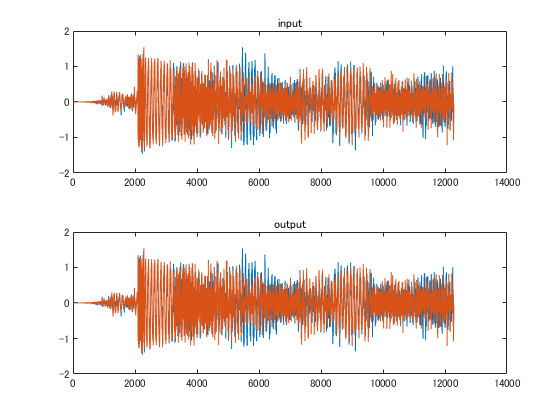

tiledlayout(2,1);
nexttile;
plot(audio_out);
title("input");

nexttile;
plot(audio_out);
title("output")


soundsc(audio_out,Fs);